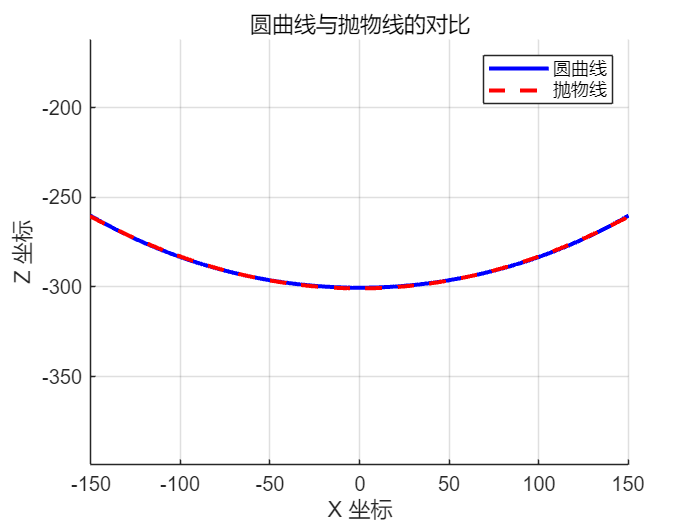

%优化确定最佳曲线之后再用这个代码
% 定义参数
R = 300.4; % 圆的半径
r_1 = R * 0.534; % 馈源舱移动的半径
m = -0.3858; %顶点处促动器的伸缩量
a = 4 * (R - m - r_1); % 抛物线的系数
h = R - m; % 抛物线的平移量

% % 定义角度范围（从240°到300°，转换为弧度） linspace生成的是一维数组
% theta = linspace(240 * pi / 180, 300 * pi / 180, 100);
% 
% % 计算圆曲线上的点
% x_circle = R * cos(theta);
% z_circle = R * sin(theta);
% 
% % 计算抛物线上对应的点
% if theta == (270*pi)/180
%     r=h;
% else
%     r=(a.*sin(theta)+sqrt((a.*sin(theta)).^2+4*a*h.*(cos(theta)).^2))/(2.*(cos(theta)).^2);
% end
% x_parabola = r.*cos(theta); 
% z_parabola = r.*sin(theta);
% 
% % 计算径向偏差
% radial_deviation = sqrt(x_circle.^2 + z_circle.^2) - sqrt(x_parabola.^2 + z_parabola.^2);

% 定义角度范围（从240°到300°，转换为弧度）
theta = linspace(240 * pi / 180, 300 * pi / 180, 120);

% 计算圆曲线上的点
x_circle = R * cos(theta);
z_circle = R * sin(theta);

% 计算抛物线上对应的点
r = zeros(size(theta)); % 初始化 r 数组,r可以看作是抛物线的极径，即曲线上任意一点到原点的距离
idx = (theta == (270*pi)/180); % 找出 theta 等于 (270*pi)/180 的索引
r(idx) = h; %如果theta等于270，分母为0，所以要专门列一下
r(~idx) = (a.*sin(theta(~idx)) + sqrt((a.*sin(theta(~idx))).^2 + 4*a*h.*(cos(theta(~idx))).^2)) ./ (2.*(cos(theta(~idx))).^2);%推出的抛物线极径公式

x_parabola = r .* cos(theta);
z_parabola = r .* sin(theta);

% 计算径向偏差
radial_deviation = sqrt(x_circle.^2 + z_circle.^2) - sqrt(x_parabola.^2 + z_parabola.^2);

% 绘制圆曲线和抛物线对比图
figure;
hold on;
plot(x_circle, z_circle, 'b', 'LineWidth', 2); % 圆曲线
plot(x_parabola, z_parabola, 'r--', 'LineWidth', 2); % 抛物线
legend('圆曲线', '抛物线');
title('圆曲线与抛物线的对比');
xlabel('X 坐标');
ylabel('Z 坐标');
grid on;
axis equal;

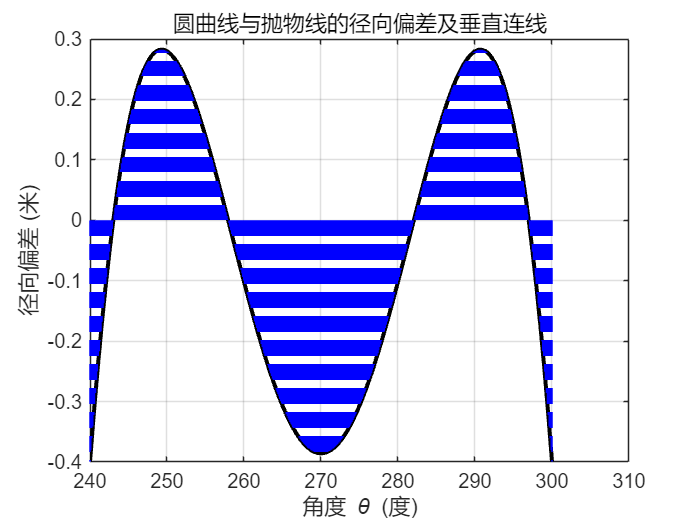


% 绘制径向偏差曲线及垂直连线
% 插值处理，从100个点插值到500个点
theta_interp = linspace(theta(1), theta(end), 500); % 新的插值角度范围
radial_deviation_interp = interp1(theta, radial_deviation, theta_interp, 'linear'); % 插值径向偏差数据

% 绘制径向偏差曲线和垂直连线
figure;
plot(theta * 180 / pi, radial_deviation, 'k', 'LineWidth', 2);
hold on;

% 绘制垂直连线
for i = 1:length(theta_interp)
    x_point = theta_interp(i) * 180 / pi;
    deviation = radial_deviation_interp(i);
    % 绘制垂直线
    line([x_point x_point], [0 deviation], 'Color', 'b', 'LineStyle', '--');
end

title('圆曲线与抛物线的径向偏差及垂直连线');
xlabel('角度 \theta (度)');
ylabel('径向偏差 (米)');
grid on;


% 显示最大偏差值
[max_deviation, max_index] = max(abs(radial_deviation));
fprintf('最大径向偏差为 %.2f 米，发生在角度 θ = %.2f 度\n', max_deviation, theta(max_index) * 180 / pi);

最大径向偏差为 0.40 米，发生在角度 θ = 240.00 度
